Синусоидальный алгоритм

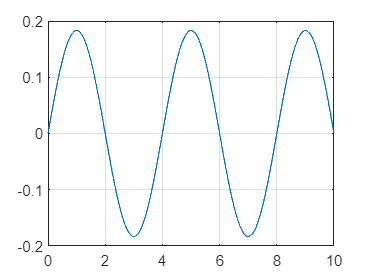

t = linspace(0,10,1000);
T = 4;
f = 2*pi/T;

phi1 = deg2rad(17);
U = (phi1*f^2) / (T- sin(f*T));


eps = U * sin(f*t);
figure
plot(t, eps);
grid on

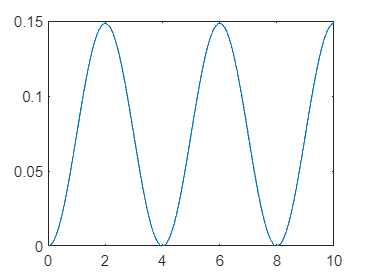



omega = (1-cos(f*t))*U/f^2;
figure
plot(t,omega)

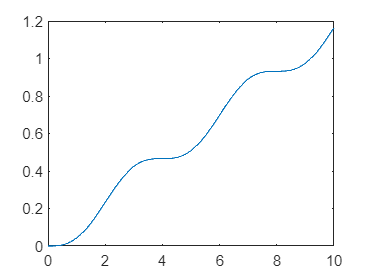


phi = t*U/f-sin(f*t)*U/f^2;


uu = phi * f /t
figure
plot(t, phi)

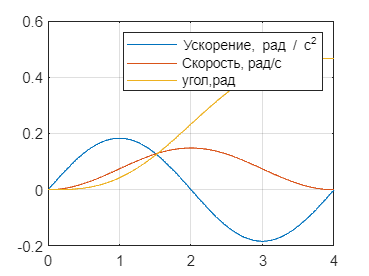




figure
plot(t, eps);
hold on
plot(t, omega);
plot(t, phi)
grid on
xlim([0.0 4])
legend("Ускорение, рад / с^2", "Скорость, рад/c", "угол,рад")



exportgraphics(gca, "sinAcc.pdf", 'ContentType', 'vector');
